Ustaw tłumienie i drgania własne:

ksi =2.3;
omega_0 = 0.49;

Definiujemy dynamikę $\ddot{x} + 2\xi\omega_{0}\dot{x} + \omega_{0}^{2}x = 0$

F = [0, 1; -omega_0^2, -2*ksi*omega_0];

Wyznaczamy wartości i wektory własne:

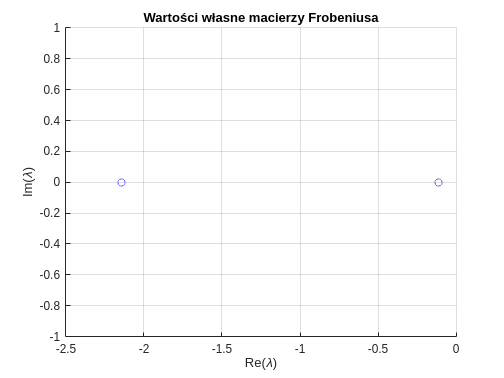

[h, lambda] = eig(F);

figure();
grid on;
hold on;
xlabel("Re(\lambda)");
ylabel("Im(\lambda)");
title("Wartości własne macierzy Frobeniusa");
for index = 1:size(lambda, 1)
    l = lambda(index, index);
    plot(real(l), imag(l), "bo");
end

Rysujemy portret fazowy:

[X1, X2] = meshgrid(-2:0.2:2);
dX1 = X2;
dX2 = -omega_0^2 * X1 - 2*ksi*omega_0 * X2;

figure();
grid on;
hold on;
xlabel("x_1");
ylabel("x_2");
title("Portret Fazowy");
xlim([-2, 2]);
ylim([-2, 2]);
legend("show");

quiver(X1, X2, dX1, dX2, 1, "DisplayName", "Pole wektorowe");

X0 = {[-2;2], [-1.5;2], [-1;2], [-0.5;2], [0;2], [0.5;2], [1;2], [1.5;2], [2;2], ...
    [-2;-2], [-1.5;-2], [-1;-2], [-0.5;-2], [0;-2], [0.5;-2], [1;-2], [1.5;-2], [2;-2], ...
    [-2;-2], [-2;-1.5], [-2;-1], [-2;-0.5], [-2;0], [-2;0.5], [-2;1], [-2;1.5], [-2;2], ...
    [2;-2], [2;-1.5], [2;-1], [2;-0.5], [2;0], [2;0.5], [2;1], [2;1.5], [2;2]};
for index = 1:length(X0)
    x0 = X0{index};
    [~, y] = ode45(@(t, x)F*x,0:0.1:100, x0);
    plot(y(:, 1),y(:, 2), "k", "HandleVisibility", "off");
end

Zaznaczamy wektory własne:

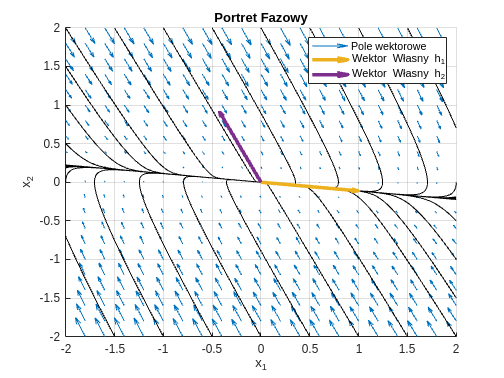

for index = 1:size(lambda, 1)
    hi = h(:, index);
    quiver(0, 0, real(hi(1)), real(hi(2)), 1, "LineWidth", 3, "DisplayName", "Wektor Własny h_"+index);
end